# calibra_mounting

Calculates the mounting calibration frame matrix from six static positions.

## Syntax

Mrot` = calibra_mounting(`Accs`, `Mags`, `num_pos`, `t_movimiento`, `vCALIBRA`, `k_inicial`, `f_s`, `t_espera`);`

## Description

`Mrot = calibra_ejez(Accs, Mags, num_pos, t_movimiento, vCALIBRA, k_inicial, f_s, t_espera_calibra)` the initial data come from signals from a triad of accelerometers `Accs` and a triad of magnetic sensors `Mags,` usually part of the same IMU. The IMU is left static during a time lapse (in seconds) `t_espera,` in six or more orientations `num_pos, `defined by their orientation matrix stored in `vCALIBRA. `The initial sample `k_inicial `must be provided, and the data sampling frequency `f_s`. The transition time between static positions must be provided also, `t_movimiento.`

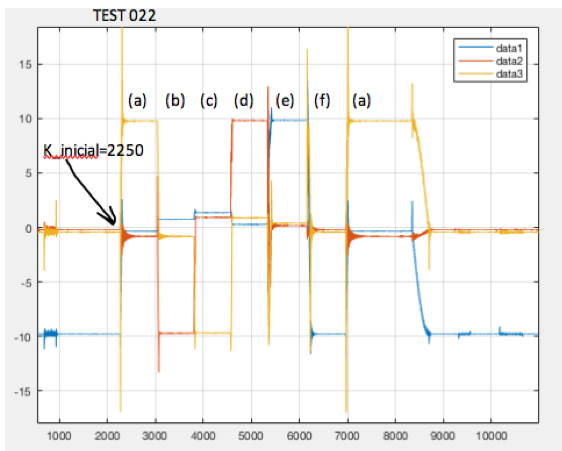

and that were generated by placing the sensor in orthogonal num_positions orientations, following the rotational calibration procedure. In the example of the figure there are 6 orientations, (a)-(f) and return to the initial (a). For each orientation we know the time it takes to reach it `t_movimiento`, and its description in the form of orientation matrix, in the rows of the matrix `vCALIBRA`, which in this case is 6x9. The initial instant `k_inicial` and the sampling frequency `f_s` are also known, the first usually known by visual inspection of the data.

## Input Arguments

`Accs            nx3 `columns matrix 

`Mags            nx3 `columns matrix 

`num_pos         `integer with the number of calibration positions 

`t_movimiento    1xnum_pos ` vector with the estimated transition time between positions

`vCALIBRA        num_posx9 `matrix, each row being the orientation matrix corresponding to the corresponding calibration position. The orientation matrix is converted to a row vector by appending their rows : [row1 row2 row3]. 

`k_inicial       `integer with the initial sample 

`f_s             `float with the sampling period  

`t_espera        `float with the static time per position (seconds)  

## Ouput Arguments

`Mrot`                          3x3 orientation matrix 

## Examples

% Cargamos los datos de un experimento de calibracion ya conocido:
filename = 'xsens_686aa.txt';

filename = 'xsens_686aa.txt'

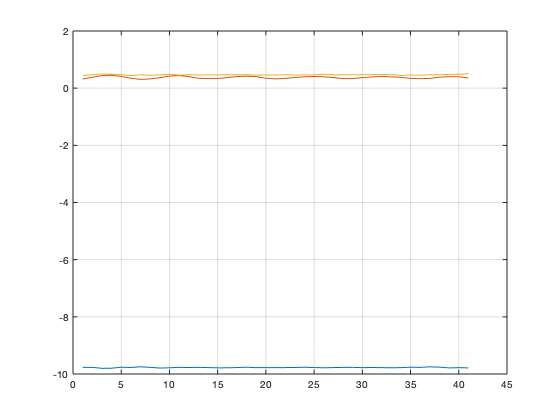

datos_todos=cargar_datos_xsens(filename);
% Visualization of the need of a proper calibration: horiz accs not in zero
plot(datos_todos.Accel(1660:1700,:)); grid;

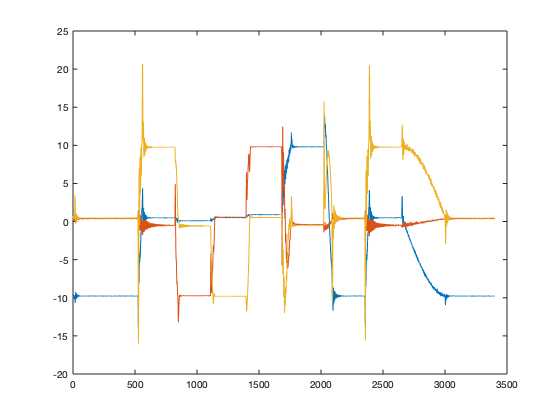

% Visualization of the data section that will be used for calibration:
plot(datos_todos.Accel(1600:5000,:))

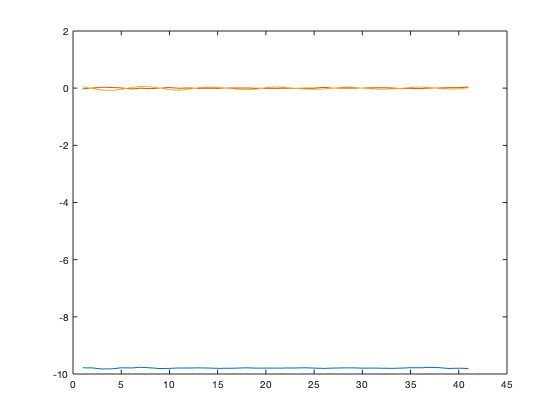


% Experimental data of this specific calibration procedure:
num_posiciones=6;   % number of calibration positions
t_movimiento= [0.4 0.4 0.4 0.4 0.75 0.75]; % time taken to change position 
t_espera_calibra=2; % time at rest in each position 
% Orientation matrices of the six calibration positions:
vCALIBRA(1,:)=[ 1  0  0   0  1  0   0  0  1];
vCALIBRA(2,:)=[ 1  0  0   0  0 -1   0  1  0];
vCALIBRA(3,:)=[ 1  0  0   0 -1  0   0  0 -1];
vCALIBRA(4,:)=[ 1  0  0   0  0  1   0 -1  0];
vCALIBRA(5,:)=[ 0  0  1   0  1  0  -1  0  0];
vCALIBRA(6,:)=[ 0  0 -1   0  1  0   1  0  0];
k_inicial=2121;     % por inspeccion
f_s=120;            % muestras/s 

% Calibracion:
Mrot=calibra_mounting(datos_todos.Accel, datos_todos.Gyro, num_posiciones, t_movimiento,...
    vCALIBRA, k_inicial, f_s, t_espera_calibra);

% Use of calibration: 
accs_cal=(Mrot*datos_todos.Accel')';

% Display of already calibrated data:
plot(accs_cal(1660:1700,:));